# ***Linear Control System***

# ***Matin Mb - 400102114***

# *CHW1*

## *Assignment N.O. 1*

*Objectives:*

- *To understand numerical ways of solving ***Ordinary Differential Equations**  

- *Defining and calling functions in matlab,*

- *To apply a signal to a system in practice using ****lsim**** and ...,*

- *To apply a signal to a system in practice using Simulink*

***Section 8 (*****Continues-Time Signals*****): ***

To plot these continuous-time signals in MATLAB, we need to sample each signal with an appropriate sampling rate $T_s$�, which may vary depending on the nature and frequency of the signal. Here’s how you can approach each signal and generate the plots.

**General Steps:**

- **Define the time interval:** $t$ goes from 0 to 12.

- **Choose sampling time **$T_s$**�****:** Choose $T_s$� based on the smoothness of each signal’s variations. A smaller $T_s$� results in a higher sampling frequency, capturing more detail.

- **Define each function and plot:** Compute the values of each function at the time points and plot them.

Initial Code:

clc; clear; close all;

Code:

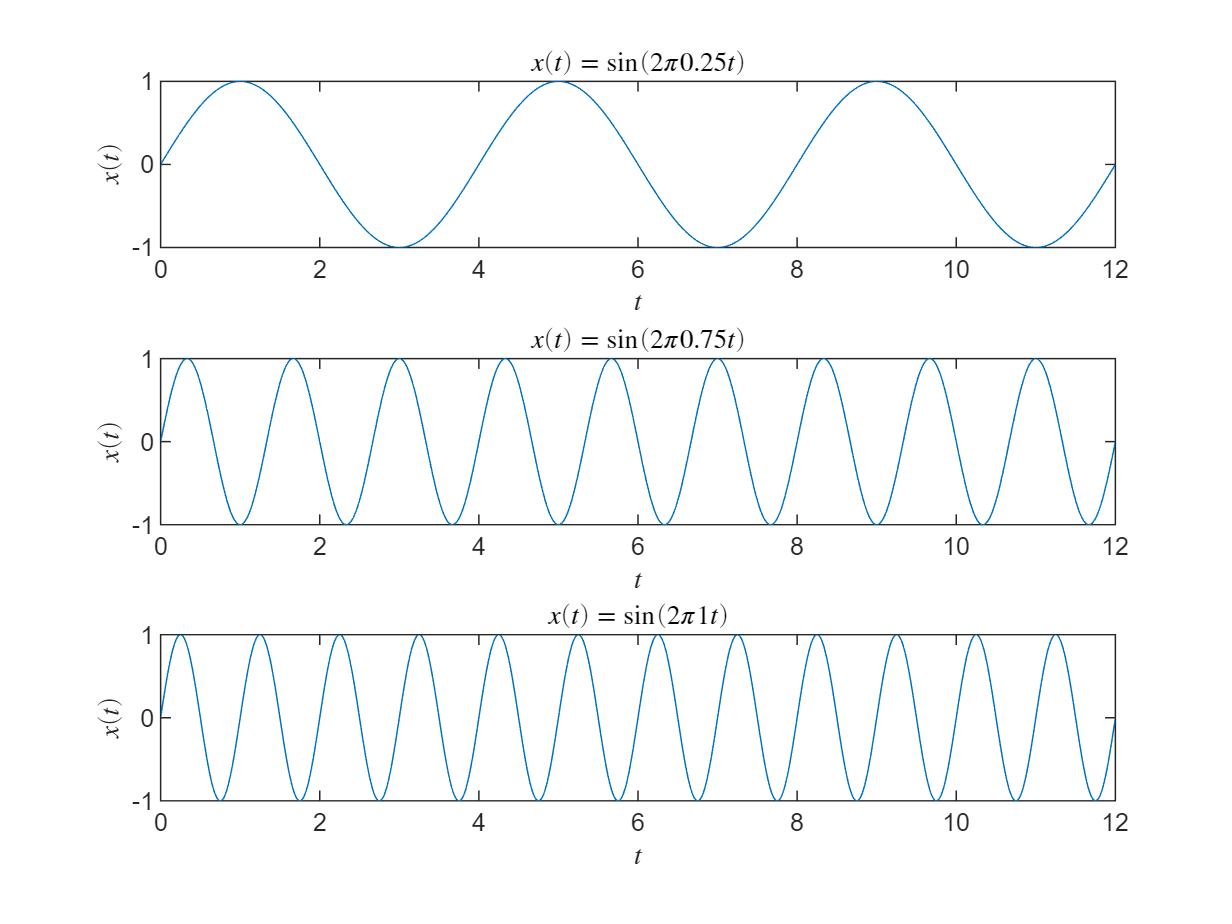

% Time settings
t_start = 0;
t_end = 12;

% Signal 1: x(t) = sin(2 * pi * alpha * t), alpha = 0.25, 0.75, 1
alpha_values = [0.25, 0.75, 1];
Ts1 = 0.01; % Adequate sampling rate for a smooth sinusoidal function
t1 = t_start:Ts1:t_end;

figure;
for i = 1:length(alpha_values)
    alpha = alpha_values(i);
    x1 = sin(2 * pi * alpha * t1);
    subplot(3, 1, i);
    plot(t1, x1);
    title(['$x(t) = \sin(2\pi ' num2str(alpha) ' t)$'], 'Interpreter', 'latex');
    xlabel('$t$', 'Interpreter', 'latex');
    ylabel('$x(t)$', 'Interpreter', 'latex');
end

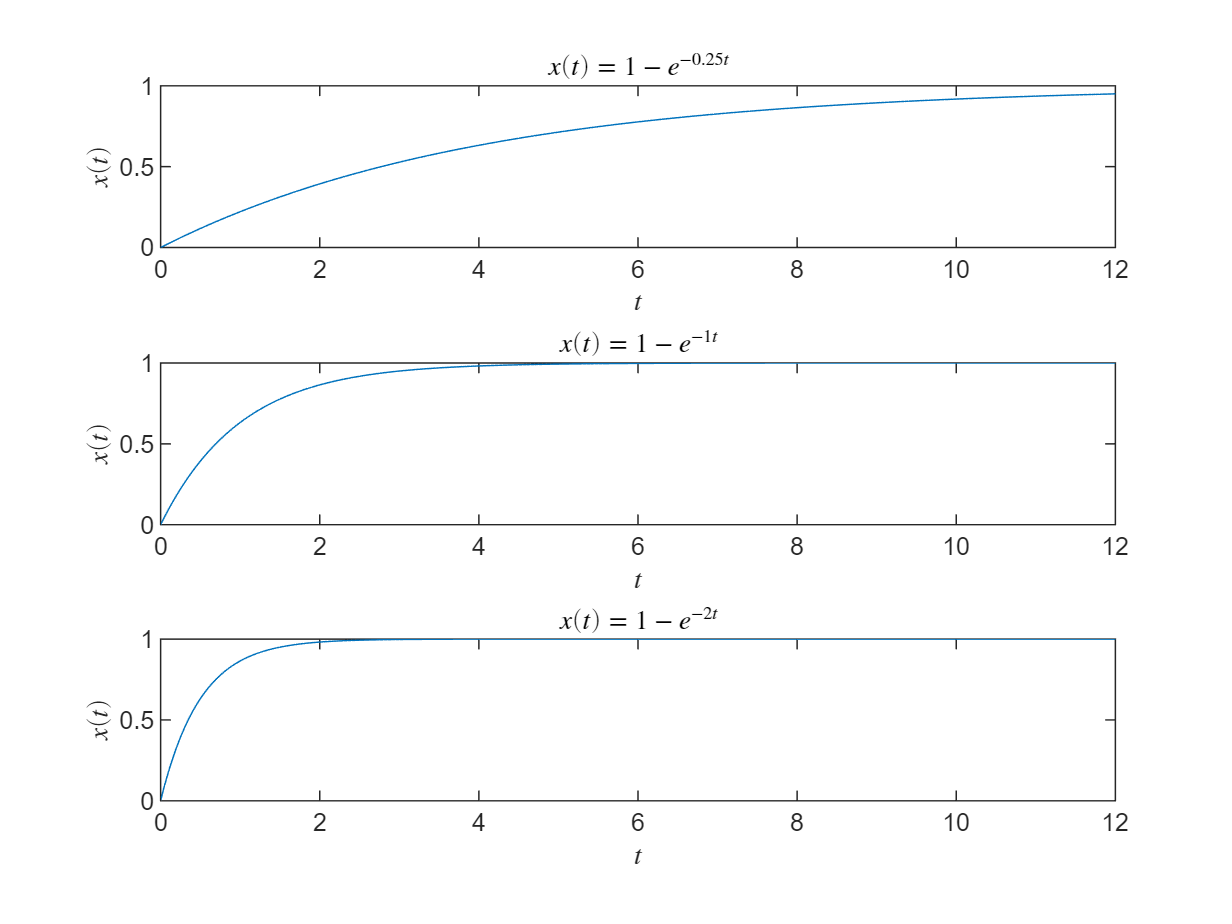


% Signal 2: x(t) = 1 - exp(-beta * t), beta = 0.25, 1, 2
beta_values = [0.25, 1, 2];
Ts2 = 0.05; % Choose a sampling rate appropriate for exponential decay
t2 = t_start:Ts2:t_end;

figure;
for i = 1:length(beta_values)
    beta = beta_values(i);
    x2 = 1 - exp(-beta * t2);
    subplot(3, 1, i);
    plot(t2, x2);
    title(['$x(t) = 1 - e^{-' num2str(beta) ' t}$'], 'Interpreter', 'latex');
    xlabel('$t$', 'Interpreter', 'latex');
    ylabel('$x(t)$', 'Interpreter', 'latex');
end

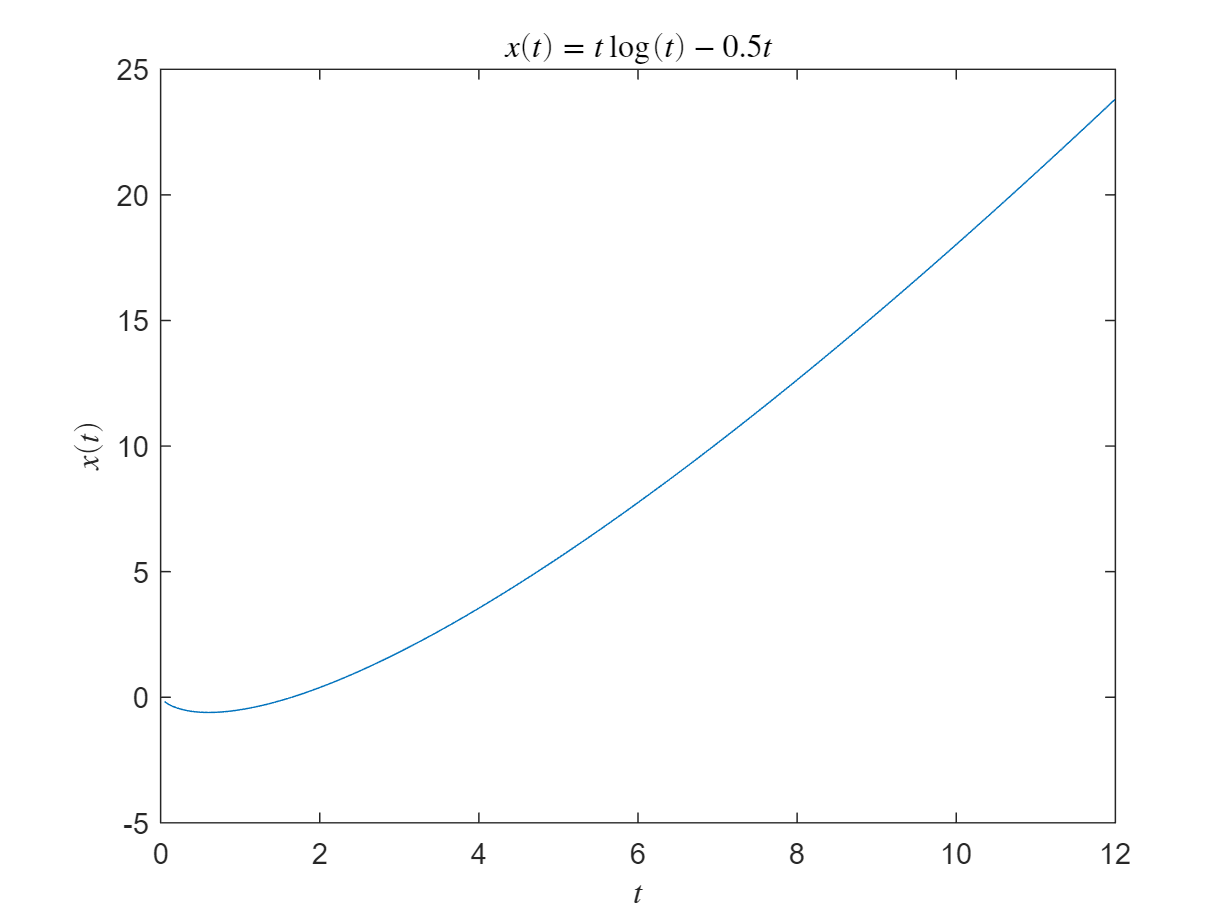


% Signal 3: x(t) = t * log(t) - 0.5 * t
Ts3 = 0.05; % Adjusted to capture the non-linear nature of the function
t3 = t_start + Ts3:Ts3:t_end; % Avoid t=0 to prevent log(0) issue
x3 = t3 .* log(t3) - 0.5 * t3;

figure;
plot(t3, x3);
title('$x(t) = t \log(t) - 0.5 t$', 'Interpreter', 'latex');
xlabel('$t$', 'Interpreter', 'latex');
ylabel('$x(t)$', 'Interpreter', 'latex');

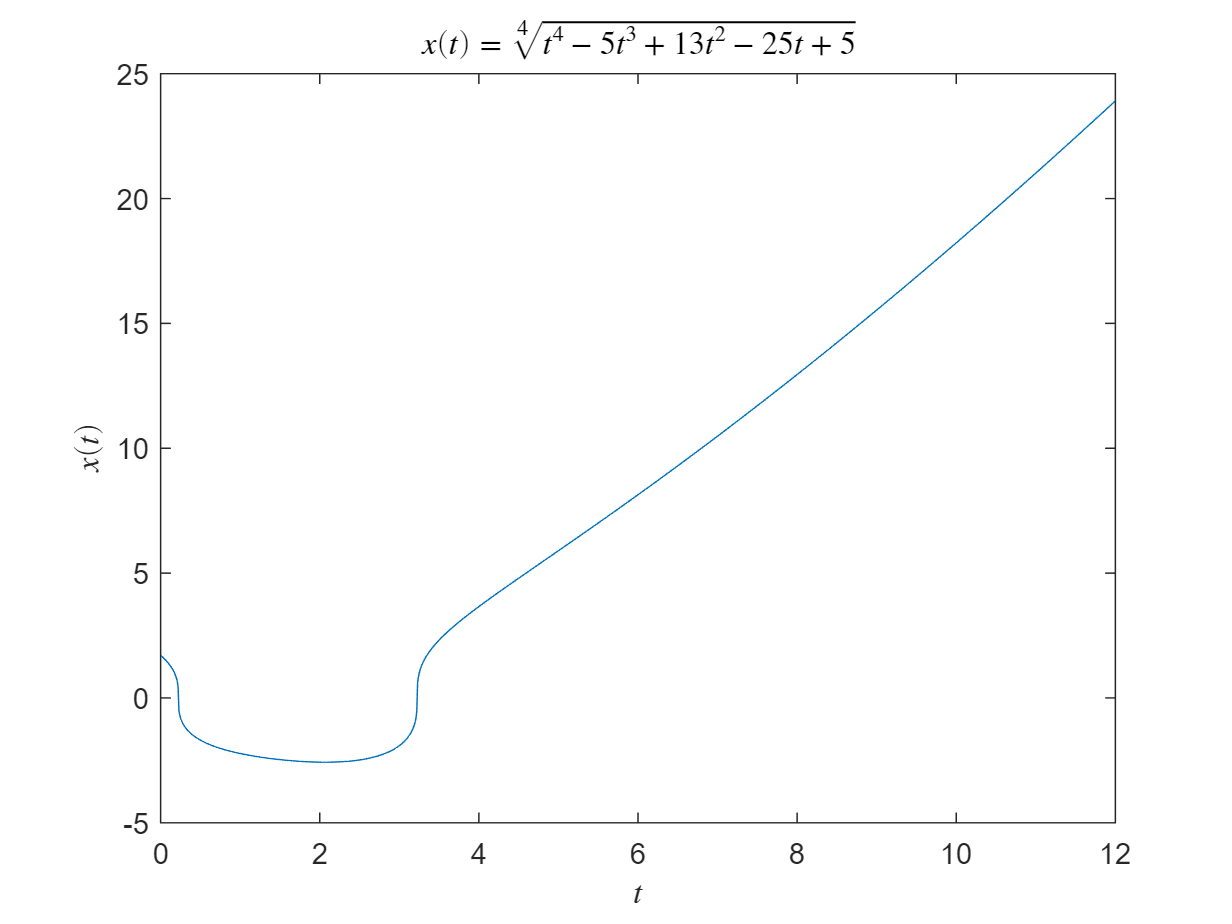

% Signal 4: x(t) = sqrt(4 * t^4 - 5 * t^3 + 13 * t^2 - 25 * t + 5)
Ts4 = 0.01; % High sampling rate to capture the polynomial behavior
t4 = t_start:Ts4:t_end;
x4 = nthroot(t4.^4 - 5 * t4.^3 + 13 * t4.^2 - 25 * t4 + 5, 3);


figure;
plot(t4, x4);
title('$x(t) = \sqrt[4]{t^4 - 5 t^3 + 13 t^2 - 25 t + 5}$', 'Interpreter', 'latex');
xlabel('$t$', 'Interpreter', 'latex');
ylabel('$x(t)$', 'Interpreter', 'latex');

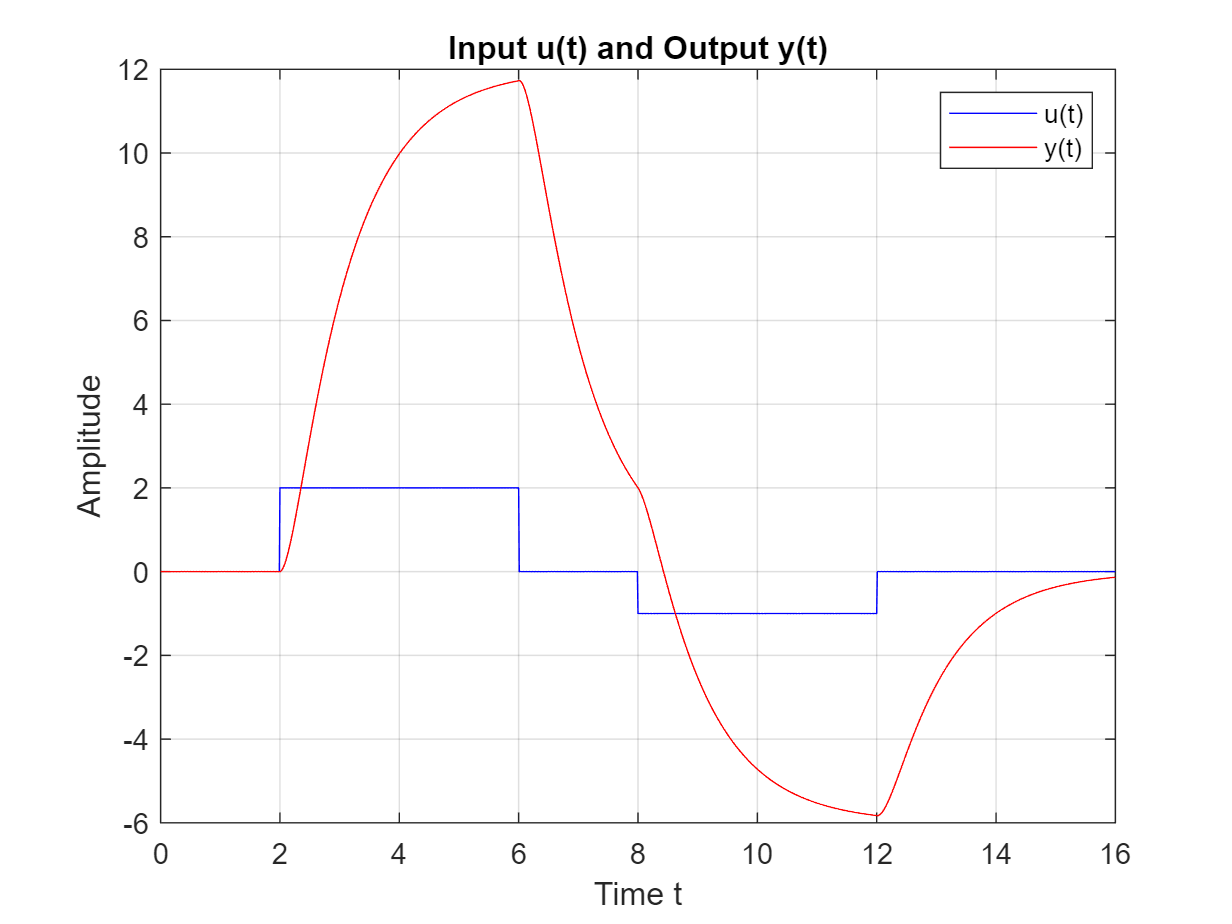

% Signal 5: (Question 7)

% Define time vector for plotting
t = 0:0.01:16;

% Define input signal u(t)
u_t = (2 * (t >= 2 & t <= 6)) - (1 * (t >= 8 & t <= 12));

% Define transfer function T(s) using symbolic variables
s = tf('s');
T_s = 6 / ((0.2 * s + 1) * (s + 1));

% Find output response y(t) by applying input u(t) through T(s)
% Using the lsim function to compute the time-domain response
y_t = lsim(T_s, u_t, t);

% Plotting both u(t) and y(t) on the same axes
figure;
plot(t, u_t, 'b', 'DisplayName', 'u(t)'); hold on;
plot(t, y_t, 'r', 'DisplayName', 'y(t)');
xlabel('Time t');
ylabel('Amplitude');
title('Input u(t) and Output y(t)');
legend;
grid on;

Note that the output of lsim() is exactly the output we calculated in Theoretical part.

***Section 9 (*****Numerical Solution of Ordinary Differential Equations*****):***

clc;
clear all;
close all;

***Code:***

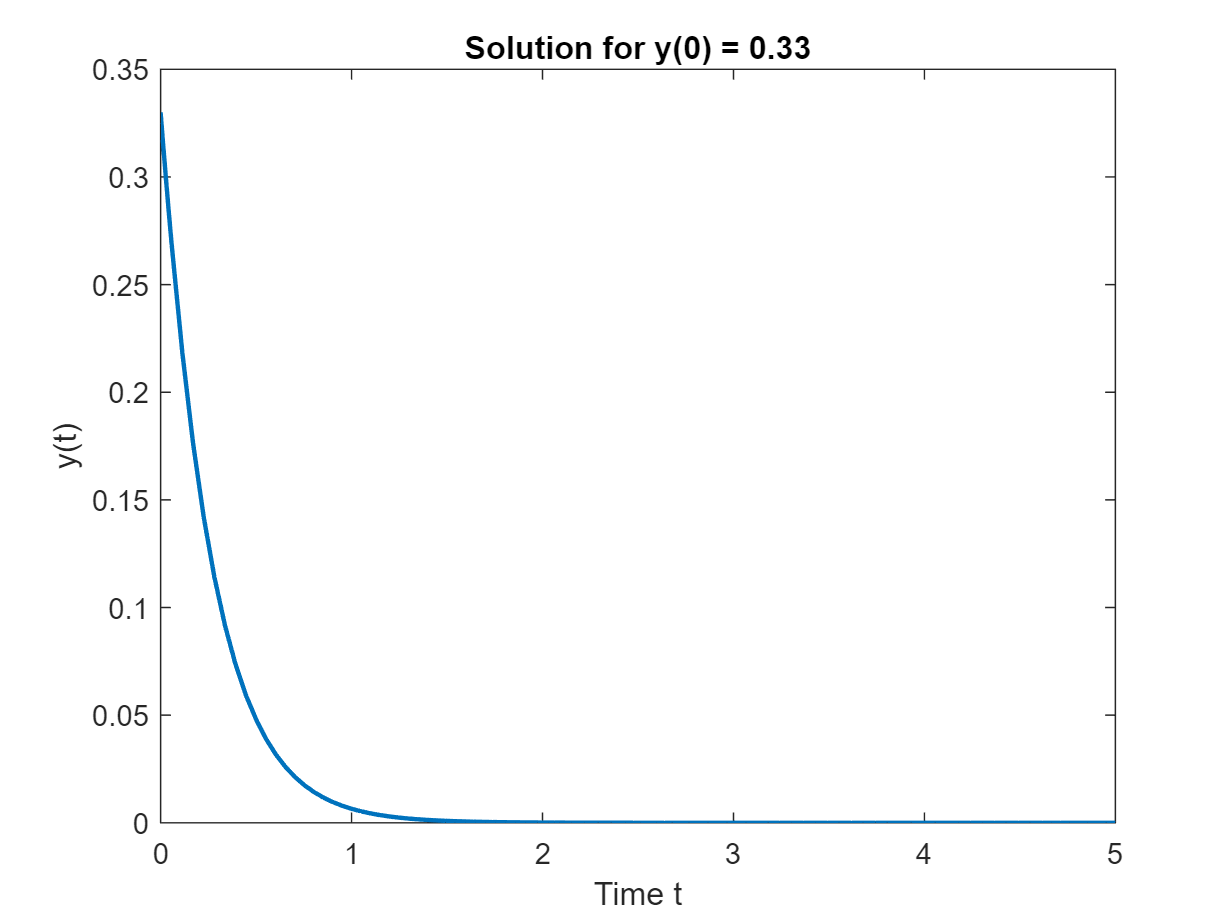

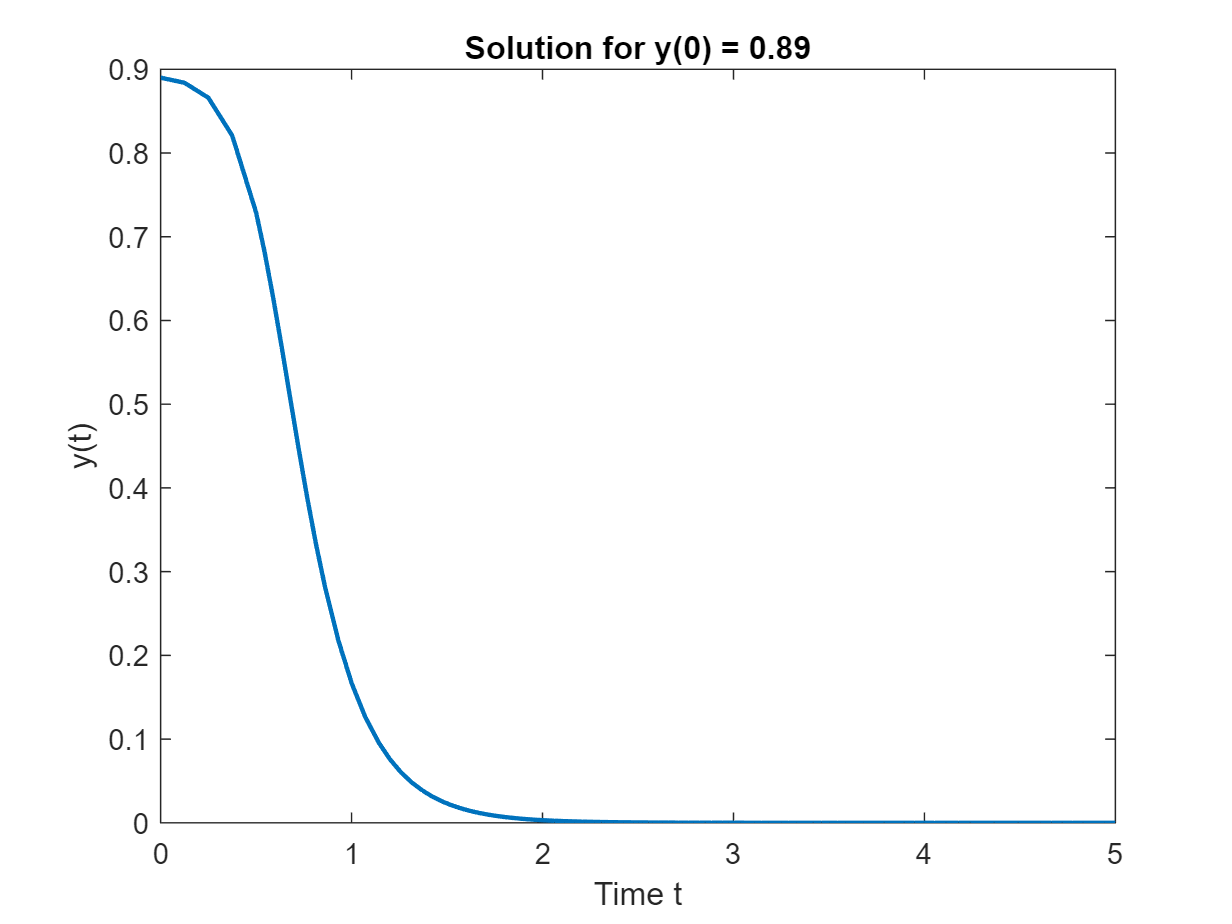

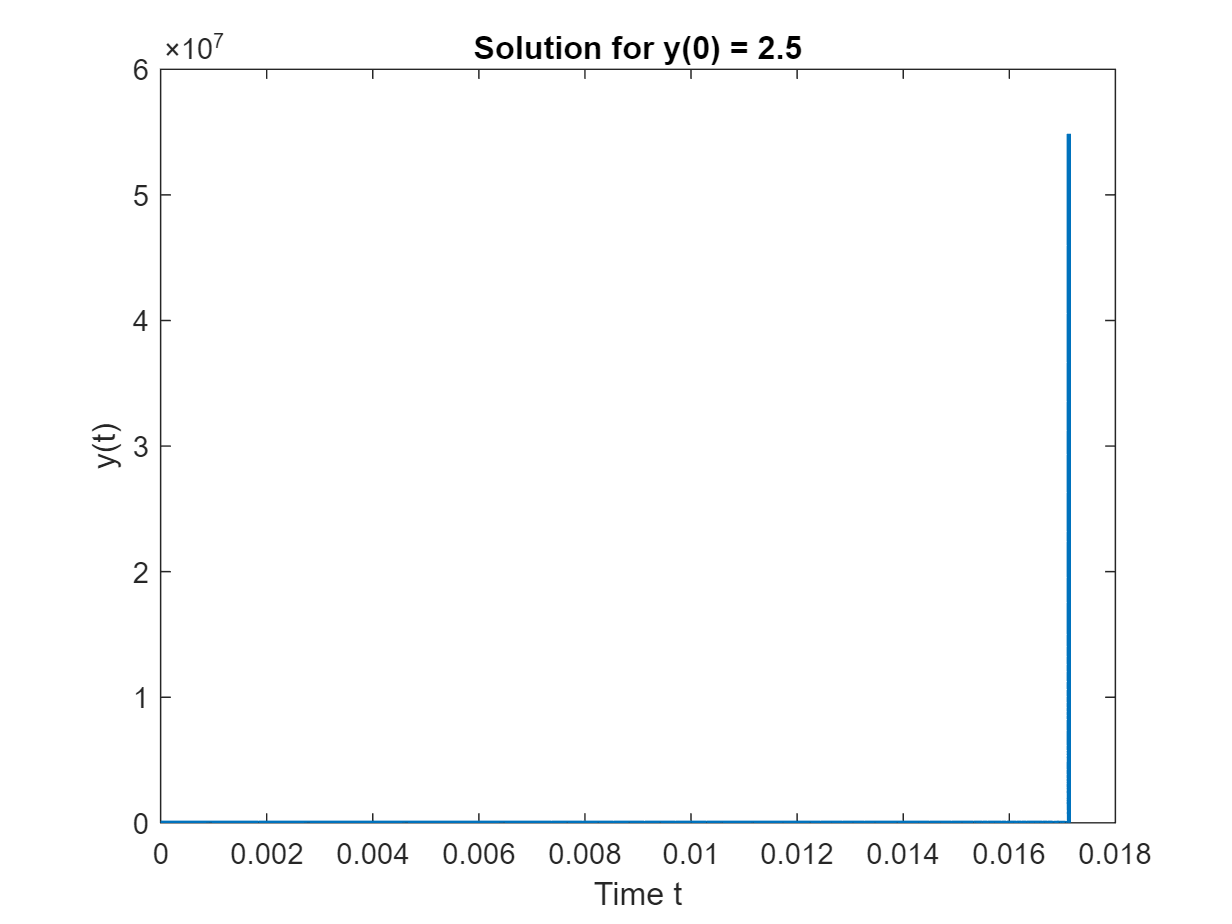

% Define the time span
tspan = [0 5];

% Initial conditions
initial_conditions = [0.33, 0.89, 2.5];


% Loop over each initial condition
for i = 1:length(initial_conditions)
    y0 = initial_conditions(i);
    
    % Solve the ODE
    [t, y] = ode45(@myODE, tspan, y0);
    
    % Plot the solution
    figure;
    plot(t, y, 'LineWidth', 1.5);

    title(['Solution for y(0) = ', num2str(y0)]);
    xlabel('Time t');
    ylabel('y(t)');
end

As we can see in the third initial value, we diverge because system is not stable for this input.

***Section 10 (*****Numerical Methods to Find the Response of a Linear System*****):***

clc;
clear all;
close all;

$H(s) = \frac{Y(s)}{X(s)} =  \frac{30}{(s+5)(s+1)} = \frac{-7.5}{s+5} + \frac{7.5
}{s+1}$ which suggests $30X(s) = (s^2 + 6s + 5)Y(s)$ which implies $30 x(t) = y"(t) + 6y'(t) + 5y(t)
$(Initial Conditions are neglected) . Now if we let $y_d [n] = y(t = nh)$ then we get: 

$
 y'(t) \equiv  \frac{y_d[n] - y_d[n-1]}{h}$  and $y''(t) \equiv \frac{y_d[n]- 2y_d[n-1] + y_d[n-2]}{h^2}$ .

 Which will result in:


$$30x(t) = 30x_d[n]= \frac{1}{h^2}(y_d[n]- 2y_d[n-1] + y_d[n-2]) +  \frac{6}{h}(y_d[n] - y_d[n-1]) + 5y_d[n]$$
 

which follows:


$$y_d[n] (\frac{1}{h^2} + \frac{6}{h} + 5 ) = (\frac{2}{h^2} + \frac{6}{h}) y_d[n-1] - \frac{1}{h^2} y_d[n-2] + 30x[n]$$
 

and by approximation we get:

$y_d[n] (1 + 6h + 5h^2) = 30h^2x[n] +(2-6h) y_d [n-1] - y_d [n-2]$ .

Finally, this is the implementation of the Euler's method for the differential equation:

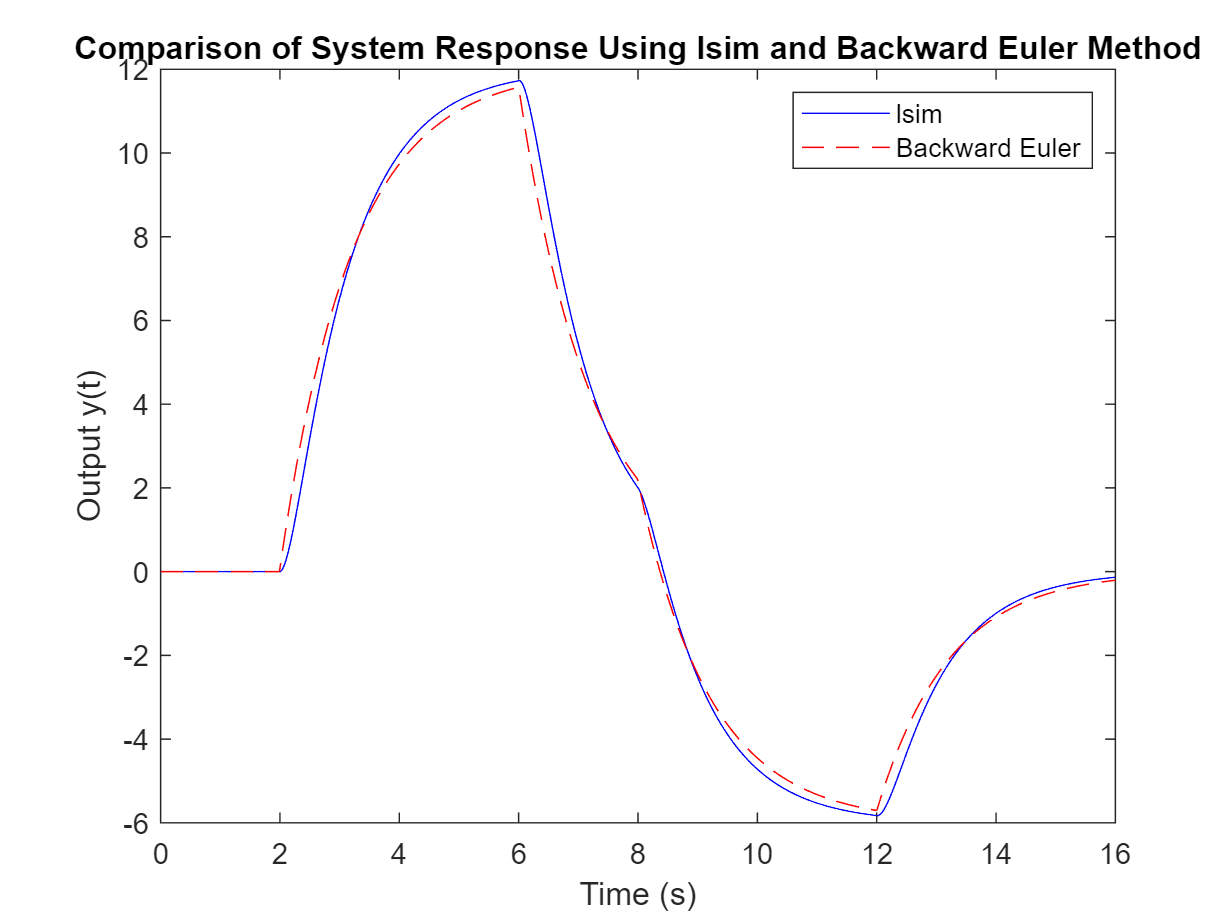

numerator = 6;
denominator = conv([0.2, 1], [1, 1]);
sys = tf(numerator, denominator);

Ts = 0.01;  % Sampling time

t = 0:Ts:16;
u = zeros(size(t));
u(t >= 2 & t <= 6) = 2;
u(t >= 8 & t <= 12) = -1;

y_lsim = lsim(sys, u, t);


% Given parameters
Y = zeros(size(t));  % Output signal initialization
Y(1) = 0;            % Initial condition
Y(2) = 0;            % Second initial condition (assumed zero)
h = Ts;              % Time step (sampling time)

X = 2* ((t >= 2) & (t <= 6)) - ((t >= 8) & (t <= 12));

for i = 3:length(t)
    % Backward Euler update formula
    Y(i) = g(i, Y(i-1), Y(i-2), X(i), h); 
end


figure;
plot(t, y_lsim, 'b', 'DisplayName', 'lsim');
hold on;
plot(t, Y, 'r--', 'DisplayName', 'Backward Euler');
xlabel('Time (s)');
ylabel('Output y(t)');
legend;
title('Comparison of System Response Using lsim and Backward Euler Method');
hold off;

As we can see in the plot, both look like the same. In fact, Backward Euler tries to fit the lsim but as we used some approximation described above,

***Section 11 (Simulink):***

Our Simulink model is shown below in details(Blocks and Modules) and is also available on the folder.

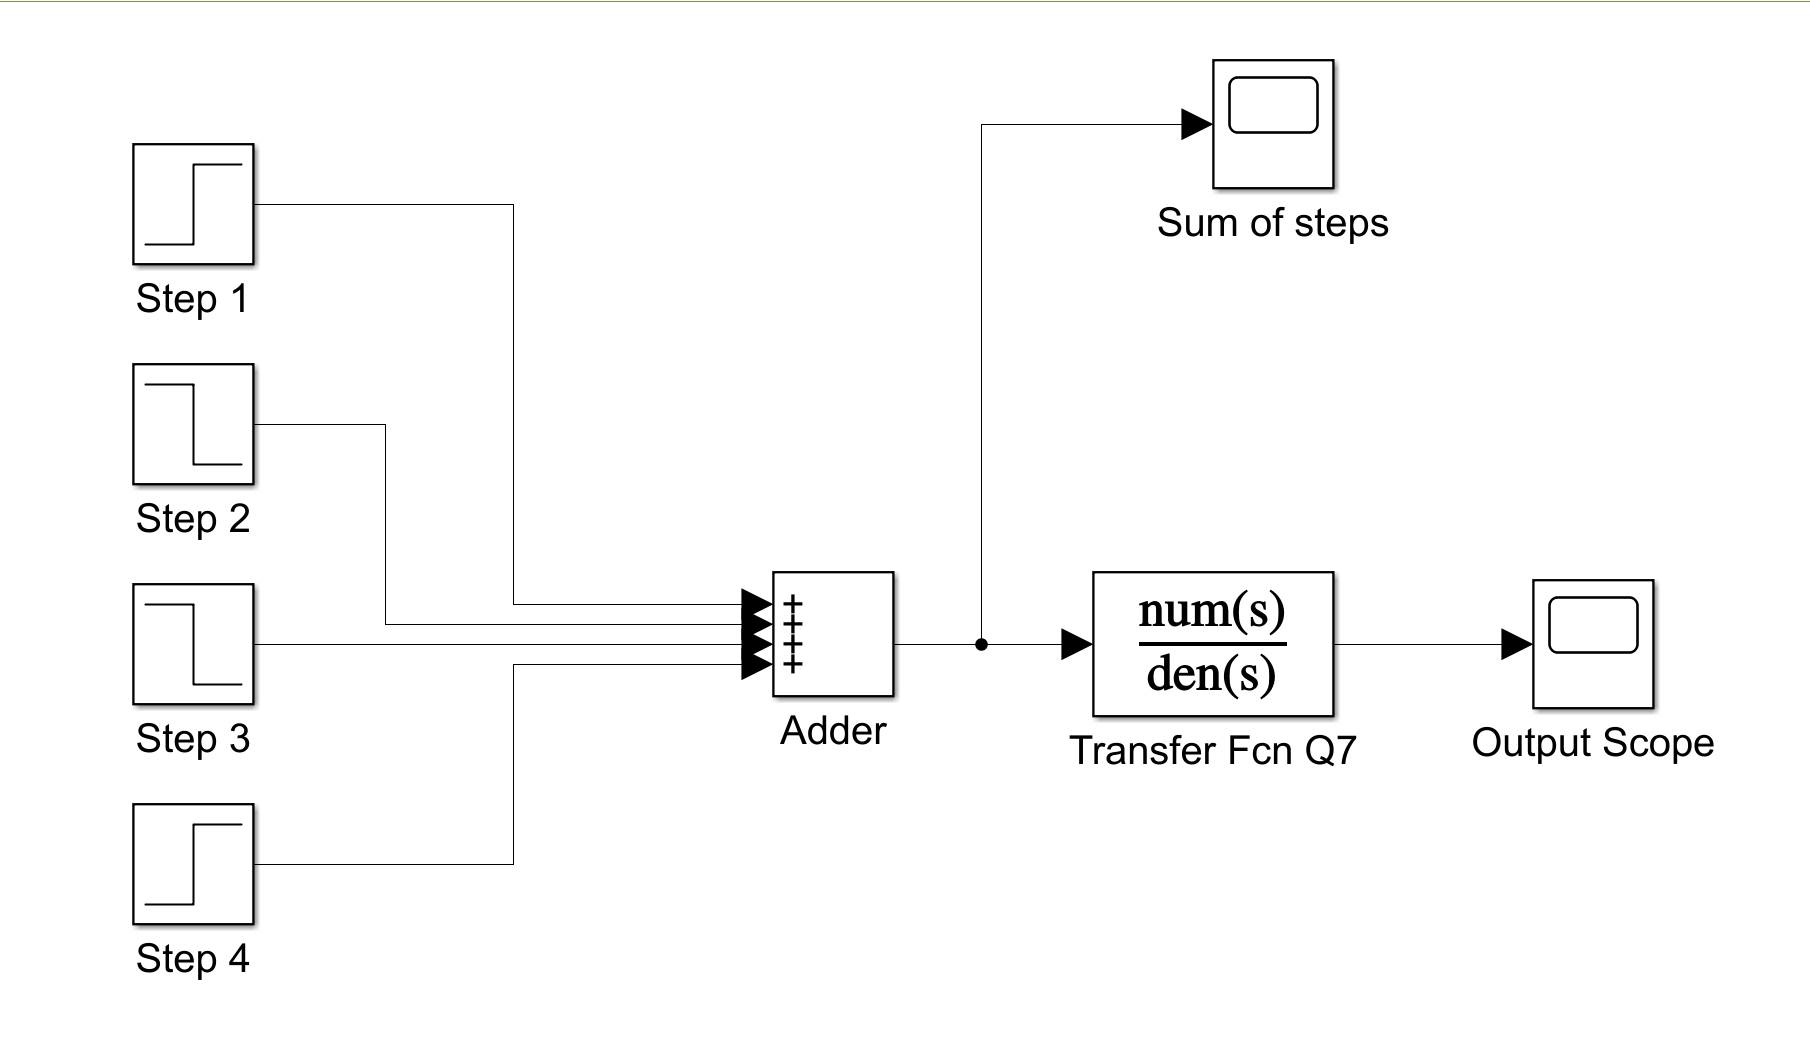

My input to the System(Transfer Fcn):

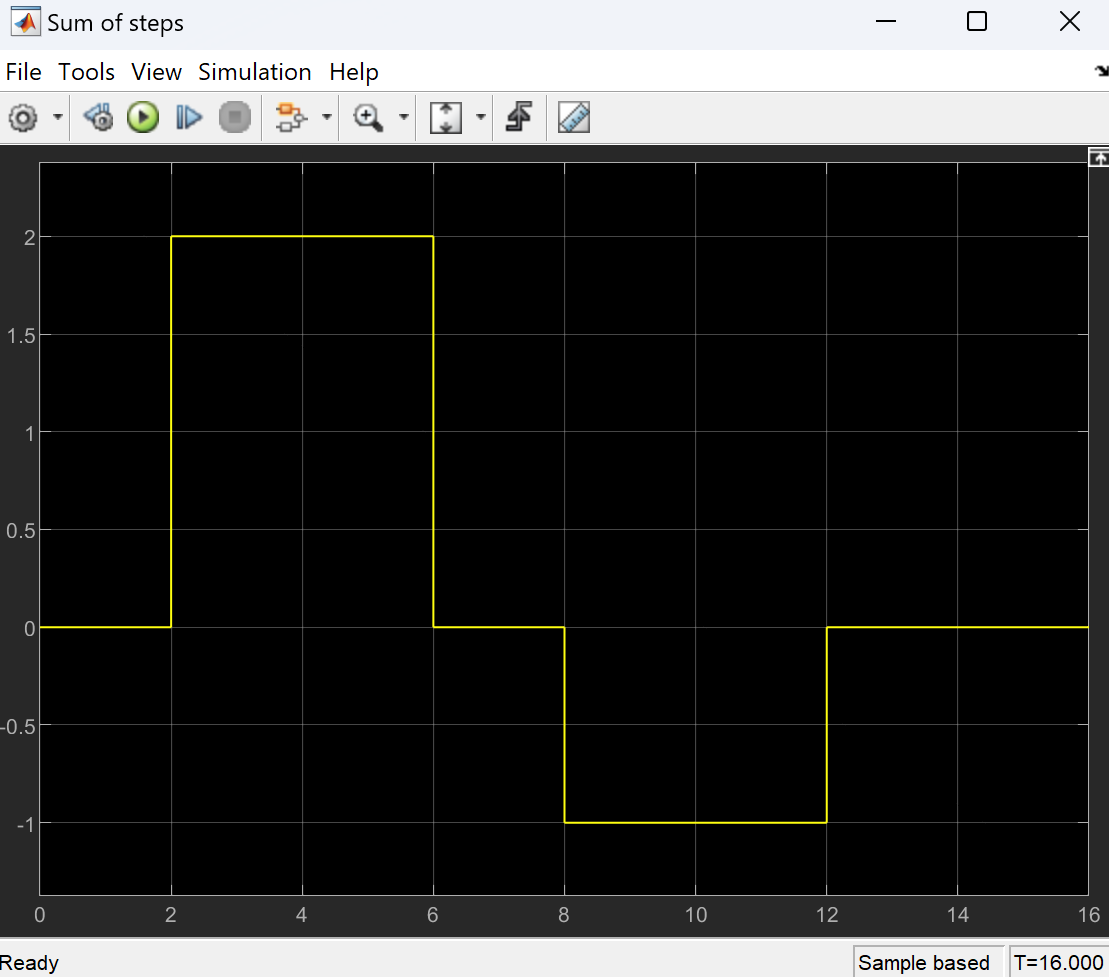

The output of the System:

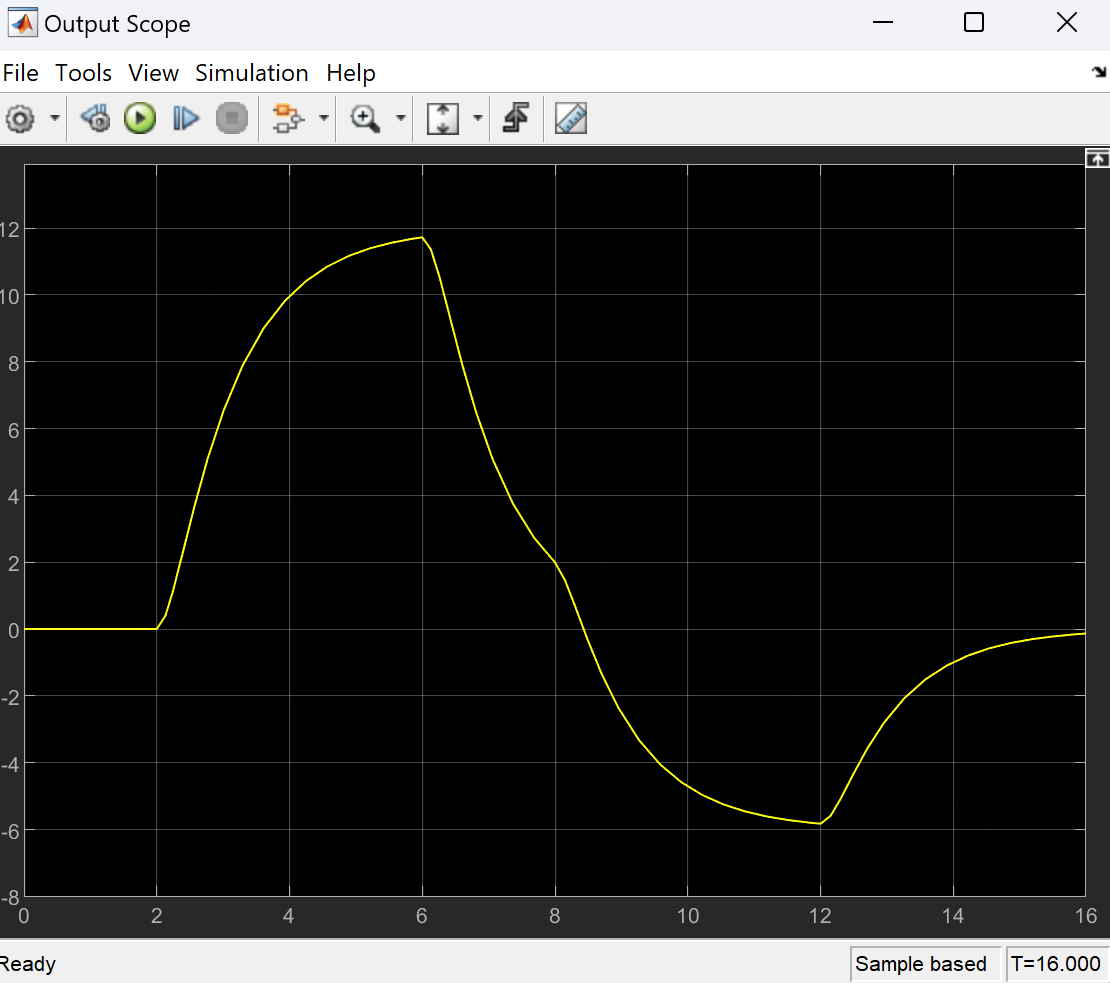

As we can see, all plots look the same but different solvers and approximations. Numerical ways look the poorest and lsim and Simulink are way better (With same Sample size).

***Used Functions:***

function dydt = myODE(t, y)
    dydt = 5*y^3 - 4*y;
end


function [result] = g(i, y_i1, y_i2, u , h)
result =  (30*h*u- y_i2 + (+8)*y_i1)/( 7 + 5*h);
end